Error using load
'Resultados\mediciones 1\control.dat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\feder\Desktop\UNS\Control_Moderno\Informe_2\Control-Moderno-Informe-2

Change the MATLAB current folder or add its folder to the MATLAB path.

c1  = load('Resultados\mediciones 1\control.dat');
t11 = load('Resultados\mediciones 1\tita1.dat');
t21 = load('Resultados\mediciones 1\tita2.dat');
ts1 = load('Resultados\mediciones 1\tiempo.dat');
v11 = load('Resultados\mediciones 1\velocidad1.dat');
v21 = load('Resultados\mediciones 1\velocidad2.dat');
w11 = load('Resultados\mediciones 1\aceleración1.dat');
w21 = load('Resultados\mediciones 1\aceleración2.dat');

c2  = load('Resultados\mediciones 2\control.dat') ;
t12 = load('Resultados\mediciones 2\tita1.dat');
t22 = load('Resultados\mediciones 2\tita2.dat');
ts2 = load('Resultados\mediciones 2\tiempo.dat');
v12 = load('Resultados\mediciones 2\velocidad1.dat');
v22 = load('Resultados\mediciones 2\velocidad2.dat');
w12 = load('Resultados\mediciones 2\aceleración1.dat');
w22 = load('Resultados\mediciones 2\aceleración2.dat');

c3  = load('Resultados\mediciones 3\control.dat') ;
t13 = load('Resultados\mediciones 3\tita1.dat');
t23 = load('Resultados\mediciones 3\tita2.dat');
ts3 = load('Resultados\mediciones 3\tiempo.dat');
v13 = load('Resultados\mediciones 3\velocidad1.dat');
v23 = load('Resultados\mediciones 3\velocidad2.dat');
w13 = load('Resultados\mediciones 3\aceleración1.dat');
w23 = load('Resultados\mediciones 3\aceleración2.dat');

c4  = load('Resultados\mediciones 4\control.dat') ;
t14 = load('Resultados\mediciones 4\tita1.dat');
t24 = load('Resultados\mediciones 4\tita2.dat');
ts4 = load('Resultados\mediciones 4\tiempo.dat');
v14 = load('Resultados\mediciones 4\velocidad1.dat');
v24 = load('Resultados\mediciones 4\velocidad2.dat');
w14 = load('Resultados\mediciones 4\aceleración1.dat');
w24 = load('Resultados\mediciones 4\aceleración2.dat');


%Condiciones iniciales
x1_0 = t14(1,1);
x2_0 = v14(1,1); %x1p
x2p_0 = w14(1,1);

x3_0 = t24(1,1);
x4_0 = v24(1,1); %x2p
w4p_0 = w24(1,1);

%Control y tiempo
control = c4;
t = ts4;
ts = t(3,1)-t(2,1);

q1  = 26.224;
q2  = 0.0027;
q3  = 0.0105;
rho = 225.2263;
r1 = rho+1;



sim("modelo\modelo.mdl")


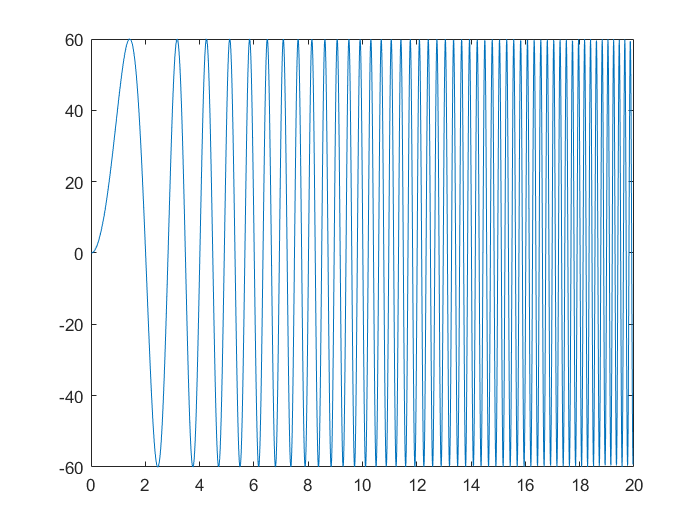

clf
plot(ts4,c4)

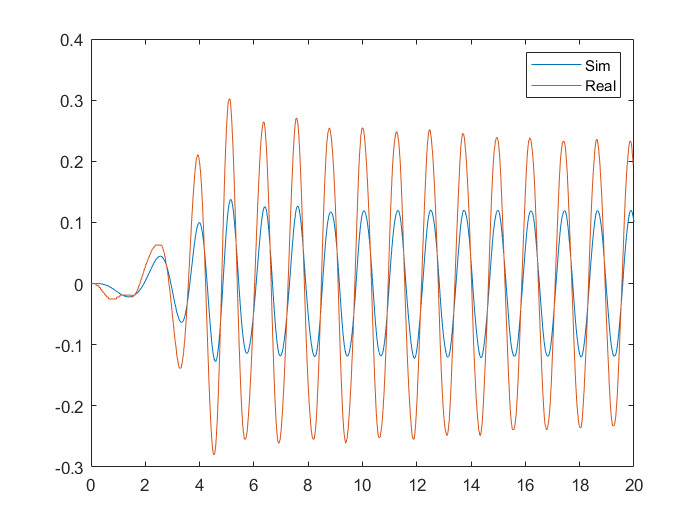

plot(t_med,x1,ts4,t14)
legend('Sim','Real')

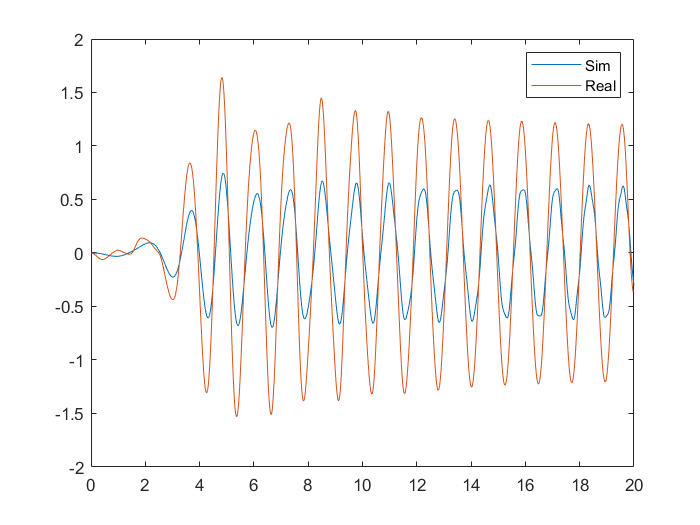

plot(t_med,x2,ts4,v14)
legend('Sim','Real')

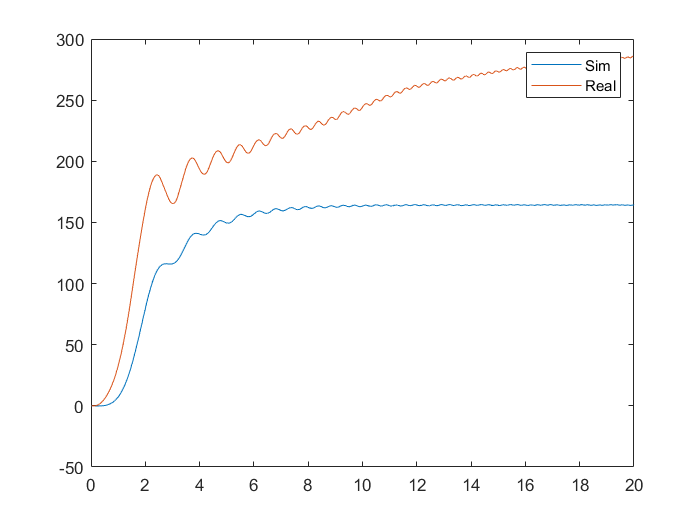

plot(t_med,x3,ts4,t24)
legend('Sim','Real')

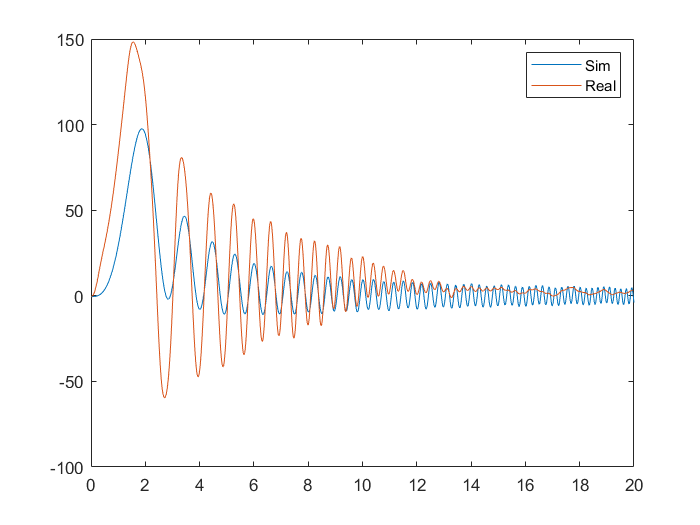

plot(t_med,x4,ts4,v24)
legend('Sim','Real')